function [rho_ML, textureMap, variance] = processReflectance(image, B, E, mesh, textureMap, K, cameraPos, cameraDir)

    image = double(image);
    B = double(B);
    E = double(E);
    textureMap = double(textureMap);
    texture_size = size(textureMap,1);
    mesh.uv_coords = mesh.uv_coords * texture_size; % 원래 uv_coords는 정규화되어 있기에 텍스처 맵 크기만큼 곱해줌

    % 이미지<->텍스처 맵 변환 위한 준비
    [set_idx, set_img_patch, set_uv_patch] = get_img_text_coords(K, cameraPos, cameraDir, mesh);
    T_affines = calculate_affine_matrices(set_img_patch, set_uv_patch);
    set_idx
    
   
    % 반사율 계산
    epsilon = 1e-6;
    rho = (image - B) ./ (E + epsilon);
    % imshow(rho, []);
    
    % 분산 계산
    sigma_squared = computeVariance(rho, B, E);
    % imshow(sigma_squared, []);

    % 워프된 분산 획득 - 텍스처 맵 크기
    sigma_texture = dispersed_warping_and_patch_based_correction(sigma_squared, T_affines, set_img_patch, texture_size, mesh);
    % imshow(sigma_texture, []);

    % 반사율 워핑 - 텍스처 맵 크기
    warpedRho = warp_texture_map(rho, T_affines, set_img_patch, texture_size);
    % imshow(warpedRho, []);

    % MLE 계산 - 텍스처 맵 크기
    rho_ML = computeMLE(warpedRho, sigma_texture, textureMap);
    % imshow(rho_ML, []);

    % 텍스처 맵 갱신
    textureMap = updateTextureMap(textureMap, warpedRho, sigma_texture);
    
    % 분산 갱신
    variance = sigma_texture;
end



function sigma_squared = computeVariance(rho, B, E)
    % 분산 계산 (식 32)
    % 입력: rho - 반사율 값, B - 산란광, E - 조명 강도
    % 출력: sigma_squared - 픽셀 기반 분산
    sigma_RN = 1e-3; % Readout noise
    sigma_squared = (rho .* E + B + sigma_RN^2) ./ (E.^2);
end

function sigma_texture = dispersed_warping_and_patch_based_correction(sigma_squared, T_affines, set_img_patch, texture_size, mesh, eta)
    % 분산 워핑 및 공간 패치 기반 보정

    % 입력 인자:
    %   sigma_squared: 카메라 좌표계의 분산
    %   T_affines: 각 면의 변환 행렬 (셀 배열)
    %   set_img_patch: 각 면에 대응하는 이미지 패치 (셀 배열)
    %   texture_size: 텍스처 맵 크기
    %   mesh: 메쉬 데이터
    %   eta: 공식 34에 사용되는 파라미터 (기본값: 10)

    % 출력 인자:
    %   sigma_texture: 보정된 텍스처 좌표계의 분산

    % 1. 카메라 좌표계의 분산을 텍스처 좌표계로 워핑
    warped_sigma = warp_texture_map(sigma_squared, T_affines, set_img_patch, texture_size);

    % 2. 메쉬 기반으로 U_s (각 패치의 크기) 계산
    Us = computePatchSizes(mesh);

    % 3. 패치 크기 기반 보정 (조건에 따라 공식 33 또는 34 적용)
    sigma_texture = zeros(size(warped_sigma)); % 결과 초기화
    for i = 1:length(Us)
        if Us(i) >= 1
            % 공식 33: |U_s| >= 1
            sigma_texture(i) = (1 / Us(i)) * warped_sigma(i);
        else
            % 공식 34: |U_s| <= 1
            sigma_texture(i) = exp(eta * (1 / Us(i) - 1)) * warped_sigma(i);
        end
    end
end

function Us = computePatchSizes(mesh)
    % 메쉬에서 각 패치의 크기 계산 (UV 좌표 기반)
    % mesh: vertices, faces, UV 정보 포함
    
    % 삼각형의 면 정보와 UV 좌표 가져오기
    faces_uv = mesh.faces.vt; % 삼각형 면에 해당하는 uv상 정점 (Nx3, 각 행이 삼각형의 정점 인덱스)
    UV = mesh.uv_coords;       % UV 좌표 (Mx2, 정점별 UV 좌표)
    
    % 삼각형 면적 계산 (UV 좌표계)
    % 각 삼각형의 세 꼭짓점의 UV 좌표
    UV1 = UV(faces_uv(:,1), :); % 첫 번째 꼭짓점
    UV2 = UV(faces_uv(:,2), :); % 두 번째 꼭짓점
    UV3 = UV(faces_uv(:,3), :); % 세 번째 꼭짓점
    
    % 벡터 계산
    edge1 = UV2 - UV1; % 첫 번째 변
    edge2 = UV3 - UV1; % 두 번째 변
    
    % 삼각형 면적 계산 (벡터 외적의 크기)
    Us = 0.5 * abs(edge1(:,1) .* edge2(:,2) - edge1(:,2) .* edge2(:,1)); % |u1*v2 - u2*v1|
    
    % Us는 각 삼각형 면적의 배열로 반환됩니다
end


function rho_ML = computeMLE(rho, variance, texture_map)
    % MLE 계산 (식 17)
    % 입력: rho - 반사율 값, variance - 품질 분산
    % 출력: rho_ML - 최대우도 반사율
    % weight = 1 ./ variance;
    % rho_ML = sum(weight .* rho, 'all') / sum(weight, 'all');
    rho_ML = rho;
end

function textureMap = updateTextureMap(textureMap, warpedRho, variance)
    % 기존 텍스처 맵과 워핑된 반사율 값의 가중 평균
    w1 = 0.5; % textureMap의 가중치
    w2 = 0.5; % warpedRho의 가중치
    weight = 1 ./ variance;
    % textureMap = (w1 .* textureMap .* weight + w2 .* warpedRho .* weight) ./ (w1 + w2);
    textureMap = (w1 .* textureMap+ w2 .* warpedRho) ./ (w1 + w2);
end

function [set_idx, set_img_patch, set_uv_patch] = get_img_text_coords(K, cameraPos, cameraDir, mesh)
    % 입력되는 메쉬의 UV좌표계는 픽셀!!! 0~1 아님!!!

    % 1. 메쉬 데이터 가져오기
    vertices = mesh.vertices;      % 정점 좌표
    faces_vertex = mesh.faces.v; % 면을 구성하는 정점 인덱스

    numFaces = size(faces_vertex, 1);     % 면의 개수

    % 월드 좌표계 -> 카메라 좌표계 변환 행렬 계산
    T_link = cameraPos'; % 나중에 전치 주의!!

    quat_link_world = quaternion(cameraDir(1), cameraDir(2), cameraDir(3), cameraDir(4));
    R_w2link = rotmat(quat_link_world, 'frame');         % 월드 -> 링크 좌표계 회전
    R_link2cam =[0 -1 0; 0 0 -1; 1 0 0];                % 링크 좌표계 -> 카메라 좌표계 회전 
    
    Proj_w2link = [R_w2link, -R_w2link*T_link; 0,0,0,1];        % 동차 변환 행렬 (월드 -> 링크)
    Proj_link2Cam = [R_link2cam, zeros(3,1); zeros(1,3), 1];    % 동차 변환 행렬 (링크 -> 카메라)
    Proj_w2cam = Proj_link2Cam * Proj_w2link;                   % 동차 변환 행렬 (월드 -> 카메라)
    
    set_idx = [];
    set_img_patch = {};
    set_uv_patch = {};
    
   % 각 면에 대해 반복
    for i = 1:numFaces
        %  면의 세 정점 좌표 (월드 좌표계)
        v1 = vertices(faces_vertex(i, 1), :); % 첫 번째 정점
        v2 = vertices(faces_vertex(i, 2), :); % 두 번째 정점
        v3 = vertices(faces_vertex(i, 3), :); % 세 번째 정점

        % 가시성 계산
        face_center = (v1 + v2 + v3) / 3; % 면의 중심
        normal = cross(v2 - v1, v3 - v1); % 면의 법선 벡터
        normal = normal / norm(normal);  % 단위 벡터로 정규화
        
        to_camera = face_center - T_link'; % 면 중심에서 카메라까지의 벡터
        visibility = dot(normal, to_camera);
        if  visibility <= 0
            % 이미지 좌표 계산
            v1_proj = project_to_image(K, Proj_w2cam, v1);
            v2_proj = project_to_image(K, Proj_w2cam, v2);
            v3_proj = project_to_image(K, Proj_w2cam, v3);
            img_patch = [v1_proj; v2_proj; v3_proj];
    
            % 텍스처 좌표계에서 UV 좌표 가져오기
            faces_uv = mesh.faces.vt;
            uv1 = mesh.uv_coords(faces_uv(i, 1), :); % 첫 번째 정점의 UV 좌표
            uv2 = mesh.uv_coords(faces_uv(i, 2), :); % 두 번째 정점의 UV 좌표
            uv3 = mesh.uv_coords(faces_uv(i, 3), :); % 세 번째 정점의 UV 좌표
            uv_patch = [uv1; uv2; uv3];

            % 계산한 값만 배열에 저장
            set_idx(end+1) = i;
            set_img_patch{end+1} = img_patch;
            set_uv_patch{end+1} = uv_patch;
            
        else
            continue; % 카메라에서 보이지 않는 면은 처리하지 않음
        end

    end % for i

end


function proj_coords = project_to_image(K, Proj_w2cam, v)
    v_hom = [v, 1]';
    v_cam = Proj_w2cam * v_hom;
    v_proj_hom = K * v_cam(1:3);
    proj_coords = round(v_proj_hom(1:2) / v_proj_hom(3));
    proj_coords = proj_coords';
end

function T_affines = calculate_affine_matrices(image_coords, uv_coords)
    % 면 개수
    numFaces = length(image_coords);

    % 변환 행렬 저장할 셀 배열 초기화
    T_affines = cell(numFaces, 1);

    % 각 면에 대해 변환 행렬 계산
    for i = 1:numFaces
        % 이미지 좌표계의 정점 (3x2)
        P_img = [
            image_coords{i}';   % (x, y) 좌표 (2x3로 전치)
            ones(1, 3)          % 동차 좌표
        ]; 

        % 텍스처 좌표계의 정점 (3x2)
        P_tex = [
            uv_coords{i}';      % (u, v) 좌표 (2x3로 전치)
            ones(1, 3)          % 동차 좌표
        ];

        % 변환 행렬 계산
        T_affines{i} = P_tex / P_img; % T_affine = P_tex * inv(P_img)
    end
end

function texture_map = warp_texture_map(image, T_affines, image_coords, texture_size)
    % image: 원본 이미지 (HxWx3)
    % T_affines: 각 면의 변환 행렬 (셀 배열)
    % image_coords: 이미지 좌표계 정점 (셀 배열)
    % texture_size: 텍스처 맵 크기 (예: [512, 512])
    
    % 텍스처 맵 초기화
    texture_map = zeros(texture_size, texture_size, size(image, 3));
    
    % 각 삼각형 면에 대해 반복
    for i = 1:length(T_affines)
        % 1. 이미지 좌표 정점 가져오기
        P_img = image_coords{i};

        % 2. 삼각형 영역의 경계 계산 (bounding box)
        x_min = max(ceil(min(P_img(:, 1))), 1);
        x_max = min(floor(max(P_img(:, 1))), size(image, 2));
        y_min = max(ceil(min(P_img(:, 2))), 1);
        y_max = min(floor(max(P_img(:, 2))), size(image, 1));
        
        % 3. 삼각형 영역의 모든 픽셀 좌표 생성
        [X, Y] = meshgrid(x_min:x_max, y_min:y_max);
        pixel_coords = [X(:), Y(:)];
        
        % 4. 픽셀이 삼각형 내부에 있는지 검사
        in_triangle = point_in_triangle(pixel_coords, P_img);
        pixel_coords = pixel_coords(in_triangle, :); % 삼각형 내부 픽셀만 선택
        
        % 5. 이미지 좌표 -> 텍스처 좌표 변환
        % 동차 좌표 사용
        pixel_coords_hom = [pixel_coords, ones(size(pixel_coords, 1), 1)]'; % 3xN
        tex_coords_hom = T_affines{i} * pixel_coords_hom; % 3xN
        tex_coords = bsxfun(@rdivide, tex_coords_hom(1:2, :), tex_coords_hom(3, :))'; % Nx2
        
        % 6. 텍스처 좌표를 텍스처 맵의 픽셀 단위로 변환
        tex_coords_pixel = round(tex_coords);
        tex_coords_pixel(:, 1) = max(min(tex_coords_pixel(:, 1), texture_size), 1); % x 좌표 제한
        tex_coords_pixel(:, 2) = max(min(tex_coords_pixel(:, 2), texture_size), 1); % y 좌표 제한
        
        % 7. 이미지 픽셀 값을 텍스처 맵에 복사 및 시각화
        for j = 1:size(pixel_coords, 1)
            img_x = pixel_coords(j, 1);
            img_y = pixel_coords(j, 2);
            tex_x = tex_coords_pixel(j, 1);
            tex_y = tex_coords_pixel(j, 2);
            
            val_img = image(img_y, img_x, :);
            double_img = double(val_img) / 255;
            texture_map(tex_y, tex_x, :) = double_img;
        end
    end
end

function is_inside = point_in_triangle(points, triangle)
    % points: Nx2 행렬 (x, y 좌표)
    % triangle: 3x2 행렬 (삼각형의 세 정점 좌표)
    % 결과: points가 삼각형 내부에 있는지 여부 (Nx1 논리 벡터)
    
    % 삼각형의 세 정점
    v1 = triangle(1, :);
    v2 = triangle(2, :);
    v3 = triangle(3, :);
    
    % 각 변의 벡터
    edge1 = v2 - v1;
    edge2 = v3 - v2;
    edge3 = v1 - v3;

    % 점에서 각 변까지의 벡터
    c1 = points - v1; % 모든 점과 v1 간의 벡터
    c2 = points - v2; % 모든 점과 v2 간의 벡터
    c3 = points - v3; % 모든 점과 v3 간의 벡터

    % 외적 계산 (2D 외적은 z 성분만 사용)
    cross1 = edge1(1) * c1(:, 2) - edge1(2) * c1(:, 1);
    cross2 = edge2(1) * c2(:, 2) - edge2(2) * c2(:, 1);
    cross3 = edge3(1) * c3(:, 2) - edge3(2) * c3(:, 1);

    % 삼각형 내부 여부 판단 (외적의 부호가 모두 같아야 함)
    is_inside = (cross1 >= 0 & cross2 >= 0 & cross3 >= 0) | (cross1 <= 0 & cross2 <= 0 & cross3 <= 0);
end

function visualizeMeshWithTexture(mesh_data, texture_image)
mesh_data.uv_coords = mesh_data.uv_coords * size(texture_image, 1);


% 2. 텍스처 매핑을 위한 준비
% faces의 정점 인덱스를 사용하여 각 면의 정점 좌표를 가져옵니다.
vertices = mesh_data.vertices

% faces의 텍스처 좌표 인덱스를 사용하여 각 면의 텍스처 좌표를 가져옵니다.
texcoords = mesh_data.uv_coords

face_3D_vertices_indexies = mesh_data.faces.v;
face_uv_vertices_indexies = mesh_data.faces.vt;

figure;

% patch 함수를 사용하여 메쉬를 그립니다.
% FaceVertexCData를 사용하여 각 정점에 텍스처 색상을 지정합니다.

% 올바른 텍스처 매핑을 위해, 각 면에 대해 반복하면서 텍스처 색상을 지정합니다.
numFaces = size(face_3D_vertices_indexies, 1);
faceVertexCData = zeros(numFaces, 3, 3); % 면 수 x 3 (RGB) x 3 (정점)

for i = 1:numFaces
    % 현재 면의 정점 인덱스 (3D)
    vertexIndices = face_3D_vertices_indexies(i, :);

    % 현재 면의 UV 좌표 인덱스
    uvIndices = face_uv_vertices_indexies(i, :);

    % 각 정점에 대한 텍스처 색상 가져오기
    for j = 1:3
        u = texcoords(uvIndices(j), 1);
        v = texcoords(uvIndices(j), 2);

        % 이미지 좌표로 변환 (반올림 및 범위 제한)
        u = max(1, min(round(u), size(texture_image, 2))); % 가로 (width)
        v = max(1, min(round(v), size(texture_image, 1))); % 세로 (height)

        % 텍스처 이미지에서 색상 가져오기
        faceVertexCData(i, :, j) = double(texture_image(v, u, :)) / 255; % 정규화 (0~1 범위)
    end
end

% patch 함수를 사용하여 텍스처 매핑된 메쉬 그리기
patch('Vertices', vertices, ...
      'Faces', face_3D_vertices_indexies, ...
      'FaceVertexCData', faceVertexCData, ...
      'FaceColor', 'interp', ... % 'texturemap' 대신 'interp' 사용
      'EdgeColor', 'none');


% 4. 뷰 및 조명 설정
view(3); % 3차원 뷰
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Mesh with Texture');
camlight;
lighting gouraud;



% 5. (선택 사항) 텍스처 이미지 표시 (별도 창)
% figure;
% imshow(texture_image);
% title('Texture Image');

end

run('code_params.m');

[rho_ML, updatedTextureMap, updatedVariance] = processReflectance(img, B, E, mesh_data, texture_map, K, cameraPos, cameraDir);

set_idx =      1     7


vertices =     0.1000   -0.1000    0.4000
    0.1000   -0.1000         0
   -0.1000   -0.1000    0.4000
   -0.1000   -0.1000         0
    0.1000    0.1000    0.4000
    0.1000    0.1000         0
   -0.1000    0.1000    0.4000
   -0.1000    0.1000         0


texcoords =          0         0
  102.4000         0
  102.4000  204.8000
         0  204.8000
  102.4000         0
  204.8000         0
  204.8000  204.8000
  102.4000  204.8000
  204.8000         0
  307.2000         0


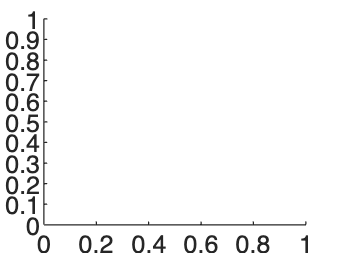

Error using patch
Value must be an Nx1 or Nx3 array of numeric type.

Error in debug_processReflectance>visualizeMeshWithTexture (line 349)
patch('Vertices', vertices, ...



% % ===== 시각화 ====



%--- 함수 호출 (테스트) ---%
visualizeMeshWithTexture(mesh_data, updatedTextureMap);